clc; clear; close all;

v = [18.0965 14.6563 15.2979 16.1005 15.5586];
f = 3000:500:5000;
k = 2*pi*f./v; 
h = 0.5835/2 * ones(size(v)) / 1000;

muestras = [1 2 3 4 5];
v = v(muestras);
f = f(muestras);
k = k(muestras);
h = h(muestras);

kh = k.*h;
% Valor inicial para fsolve
eta0 = 0.85;

% Opciones de fsolve
options = optimset('Display','off');

% Usamos arrayfun para aplicar fsolve a cada par (k(i), h(i))
eta_sol = arrayfun(@(khi) ...
    fsolve(@(eta) 4*eta.*tanh(eta*khi)./tanh(khi) - (1+eta.^2).^2, ...
           eta0, options), ...
    kh);

disp('Soluciones para eta:')

Soluciones para eta:


disp(eta_sol)

    0.9455    0.8989    0.8833    0.8708    0.8416



rho = 1050;

x = eta_sol.^2

x =     0.8940    0.8080    0.7803    0.7583    0.7082


y = rho*v.^2

y = 1.0e+05 *

    3.4386    2.2555    2.4573    2.7219    2.5417


% Ajuste lineal (grado 1)
p = polyfit(x, y, 1);

% Pendiente y ordenada al origen
m = p(1);
b = p(2);

disp(['Recta ajustada: y = ' num2str(m) ' * x + ' num2str(b)])

Recta ajustada: y = 440648.5155 * x + -79715.0592


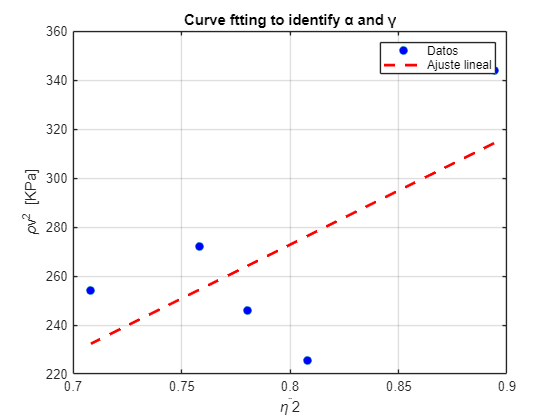


% Calcular valores ajustados
y_fit = polyval(p, x);

% Graficar
figure();
plot(x, y/1000, 'o', 'MarkerFaceColor', 'b'); hold on
plot(x, y_fit/1000, '--r', 'LineWidth', 2);
title('Curve ftting to identify α and γ')
legend('Datos', 'Ajuste lineal')
xlabel('\eta^¨2'); ylabel('\rhov^2 [KPa]');
grid on

% Resultados
alpha = b

alpha = -7.9715e+04

gamma = -m

gamma = -4.4065e+05


stress = alpha - gamma

stress = 3.6093e+05

strain = -1 + (alpha/gamma)^(1/3)

strain = -0.4344

young = stress/strain

young = -8.3081e+05